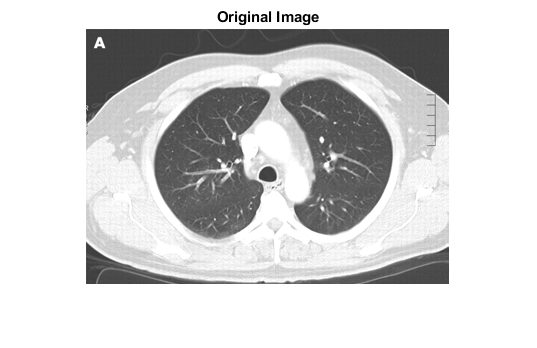

clc;
clear;
close all;

img = imread('normallung1.jpg');
img = imresize(img, [255 NaN]);
imshow(img);title('Original Image');

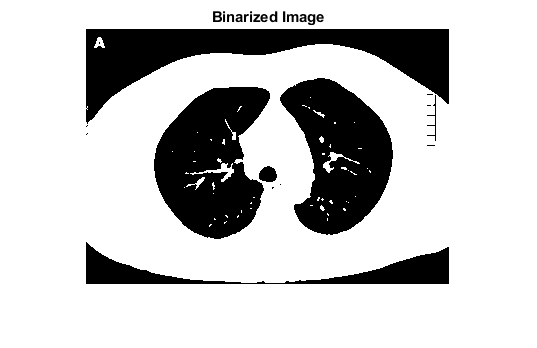

level = graythresh(img);
img_bin = rgb2gray(img);
img_bin = imbinarize(img_bin, level);
imshow(img_bin);title('Binarized Image');

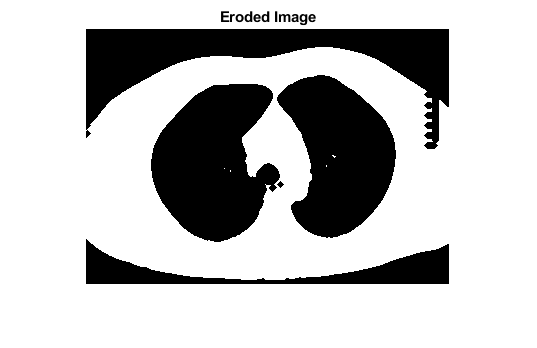

se = strel('diamond',3);
img_er = imerode(img_bin,se);
% img_er = bwmorph(img_bin,'erode',1);
imshow(img_er);title('Eroded Image');

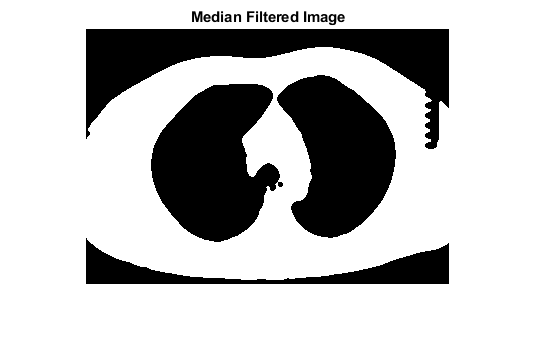

img_med = medfilt2(img_er, [5 5]);
imshow(img_med);title('Median Filtered Image');

% background = imopen(img_med,strel('disk',8));
% imshow(background);title('Background Image')

% im_sub = imsubtract(img_med,background);
% imshow(im_sub);title('Substracted Cancer');

% im_sub_er = bwmorph(im_sub,'erode',1);
% im_sub_dil = bwmorph(im_sub_er,'dilate', 1);
% imshow(im_sub_dil);title('Substracted Cancer with Erosion and Dilation');

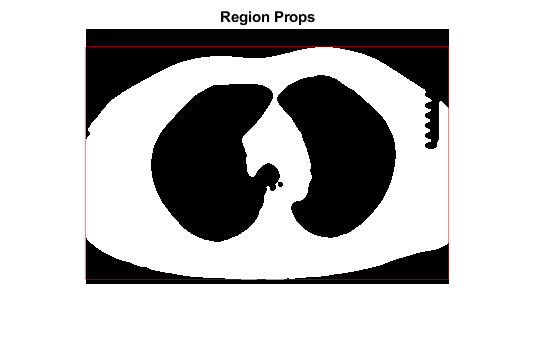

pixelH = 45382

BWr = regionprops(img_med, 'BoundingBox', 'Area', 'Image');
figure, imshow(img_med), title('Region Props');
hold on;
pixelH = [];
pixelW = [];
for i=1:size(BWr,1)
    rectangle('Position', BWr(i).BoundingBox,'edgecolor','red');
%    pixelT = pixelT + BWr(i).Area;
    pixelH(1,i) = BWr(i).Area
end

cc = bwconncomp(img_med)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [255 363]
      NumObjects: 1
    PixelIdxList: {[45382×1 double]}


num = cc.NumObjects;

arr = sort(pixelH, 'descend');
arrMaxP = arr(1,num);
[c_max, idx_max] = max(arrMaxP);
T = 1500

T = 1500

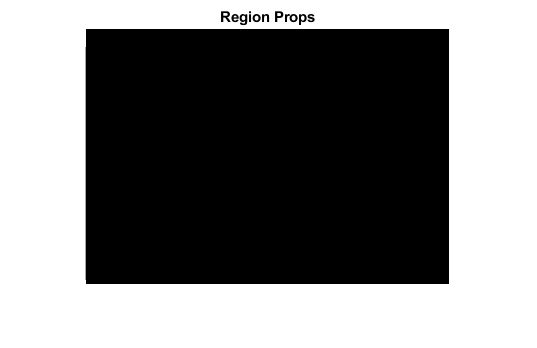




removeMask = [BWr.Area]>T; 
BWremove2 = img_med;
BWremove2(cat(1, cc.PixelIdxList{removeMask})) = false;
BWremove2 = bwmorph(BWremove2, 'open', Inf);
imshow(BWremove2);


cc_rem = bwconncomp(BWremove2);
num_canc = cc_rem.NumObjects;

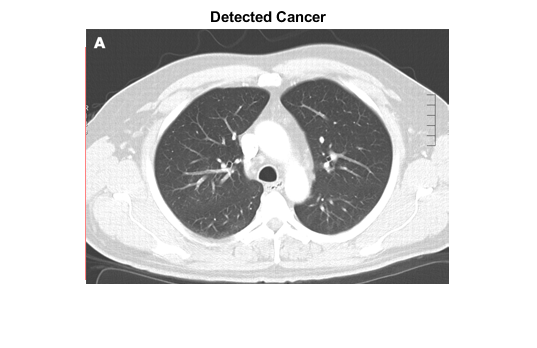


cancer = regionprops(BWremove2,'BoundingBox','Area');
 

 
imshow(img);title('Detected Cancer')
 
hold on ;


for cancers=1:size(cancer,1)
    size(cancer)
    rectangle('Position', cancer(cancers).BoundingBox,'edgecolor','red');
end

fprintf('***** ANALYSIS RESULT ******')

***** ANALYSIS RESULT ******

if (num_canc > 0)
    fprintf('This lung have cancer (abnormal)');
else
    fprintf('This lung is normal')
end

This lung is normal